# Multivariable Anonymous Functions

## Task 1

Create a function handle `myCirc` to an anonymous function for f(x,y)=x2+y2−4. 

Use element-wise operators (`.^`) in your implementation. 

myCirc=@(x,y) x.^2+y.^2-4

myCirc = function_handle with value:
    @(x,y)x.^2+y.^2-4


## Task 2

Evaluate `myCirc` at the point (0,1). Assign the result to the variable `z`.

z=myCirc(0,1)

z = -3

## Task 3

You can visualize a function of two variables by creating a *surface plot*.

A surface plot is defined by z=f(x,y). For each (x,y) pair, the function is evaluated to find z, then a surface is created by connecting all the (x,y,z) points.

You can create a surface plot in MATLAB by passing a function handle to the `fsurf` function.

`fsurf``(``myFun``)`

Task

Use `fsurf` to create a surface plot of `myCirc`.

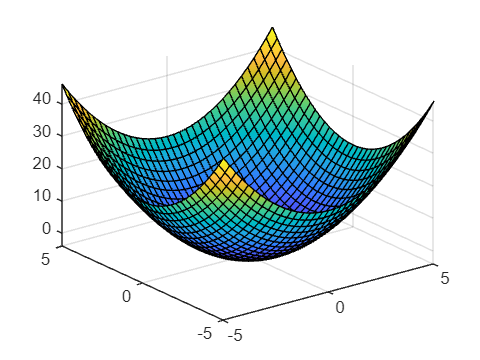

fsurf(myCirc)

## Task 4

By default, `fsurf` plots the function over the interval -5 to 5.  You can also create a surface plot over a specified interval.

`fsurf``(``myFun``,``[``-1` `1``])`

The interval will apply to both the x and y variables. 

To specify different intervals for x and y, use a four element vector containing the x interval followed by the y interval.

`fsurf``(``myFun``,``[``-1` `1` `0` `5``])`

Task

Create a surface plot of `myCirc` over the interval -3 to 3.

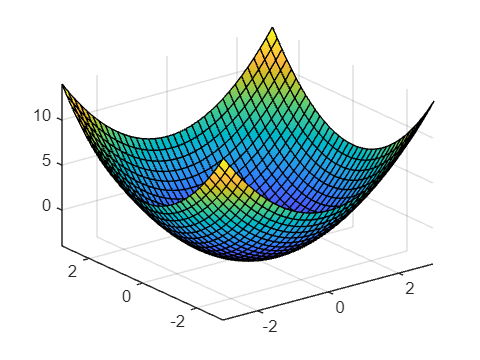

fsurf(myCirc,[-3 3])

## Task 5

Add the plane z=0in red to your plot of `myCirc`. Use `fsurf` with the function `0` and a second input `"r"` to specify the color. 

Remember to use `hold` `on` and `hold` `off` to add to your existing plot.

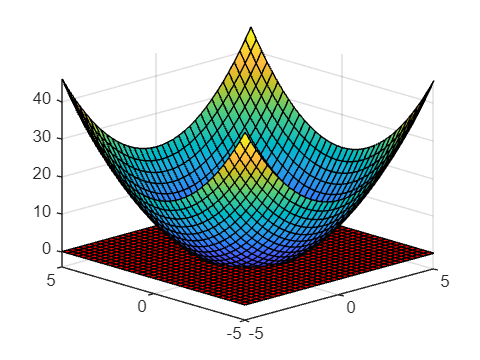

fsurf(myCirc)
hold on
fsurf(0,"r")
hold off

view([-44.1 21.6])

## Further Practice

To get a better view of the intersection of the two surfaces, you can rotate your plot. Select the   button in the upper right corner of the figure, then click and drag your plot to change the viewing angle.  

The `fsurf` function is one of many functions for multivariable visualization in MATLAB. Try using the `fcontour` function to make a contour plot of `myCirc`. How does the contour plot relate to the surface plot? 

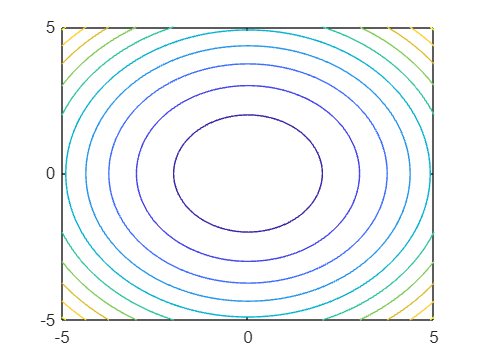

fcontour(myCirc)